### **Group: Aleix Granero, Michal Szabó**

**10.11.2021**

close all; clc; clear

# Practice 5. Morphological operators.

## Exercise 1

I = imread('text.tif');

#### ** 1. Binarization of the input image**

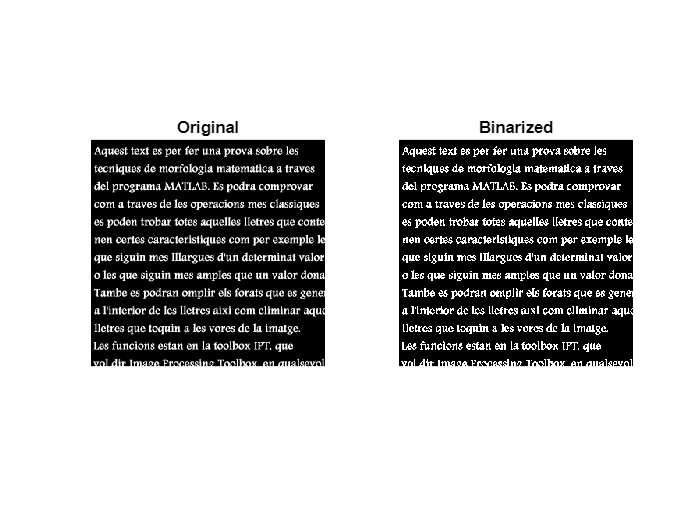

f = imbinarize(I,"global");
figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(f), title('Binarized')

#### **Comparing the results of the following functions on a binarized sample image (f)**

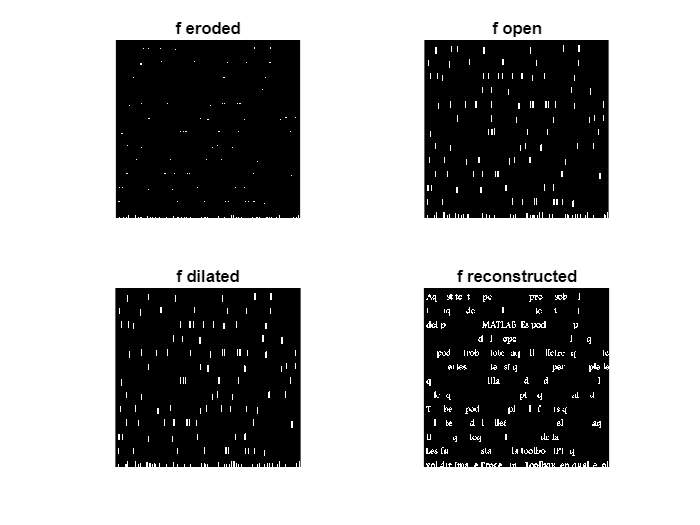

fe = imerode(f, ones(10,1));
fo = imopen(f, ones(10,1));
fd = imdilate(fe, ones(10,1));
fobr = imreconstruct(fe,f);

figure
subplot(2,2,1), imshow(fe), title('f eroded')
subplot(2,2,2), imshow(fo), title('f open')
subplot(2,2,3), imshow(fd), title('f dilated')
subplot(2,2,4), imshow(fobr), title('f reconstructed')

#### a) Only characters that match with the white pixels of the pattern

- **Mask 1**

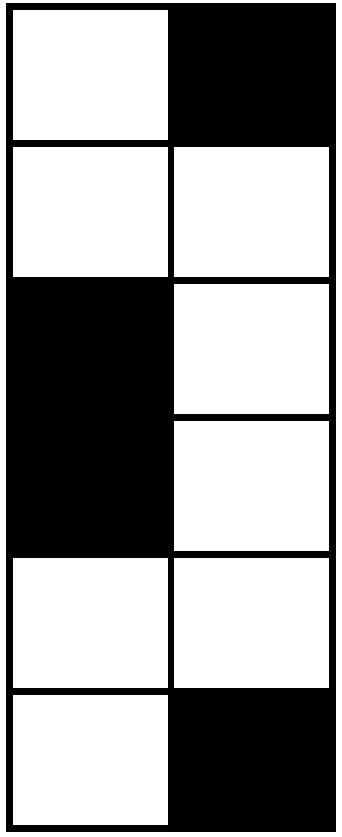

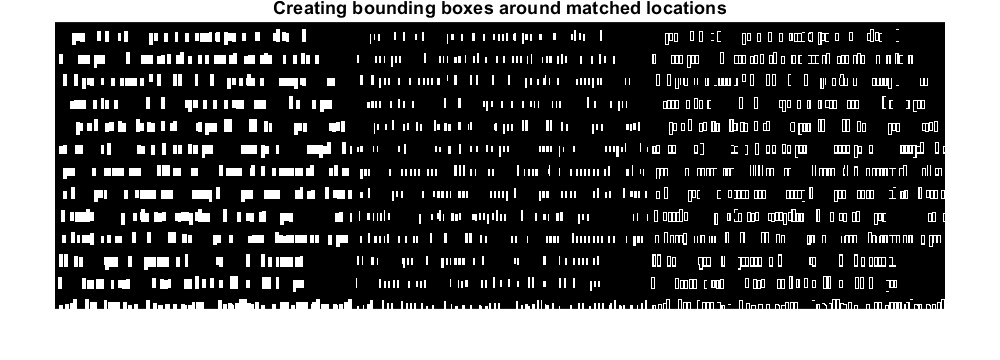

mask_W1 = [1 0;1 1;0 1;0 1;1 1;1 0];
match_W1 = imerode(f,mask_W1);

% Mask for highlighting the results
f_mask = ones(8,4);     % Around the located area
f_mask_e = ones(6,2);   % minus the inside

% Highlighting locations
match_W_res = imdilate(match_W1,f_mask);        % We put big filled box on matched locations (one pixel bigger than mask)
match_W_res_e = imdilate(match_W1,f_mask_e);    % We put small filled box on matched locations (size of mask)
match = match_W_res-match_W_res_e;              % We than substract the small box from bigger box to create bounding box

figure
montage({match_W_res,match_W_res_e,match},'Size',[1 3])
title('Creating bounding boxes around matched locations')

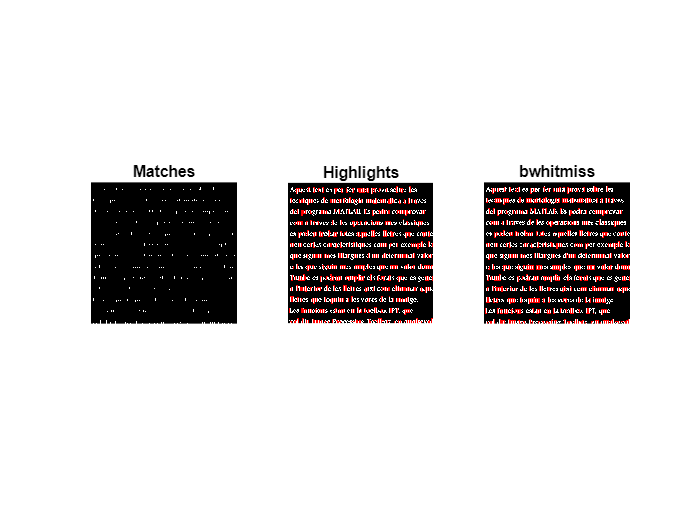

% Representing the solution in color
result_a = cat(3,f+match,f-match,f-match);

% Comparison with bwhitmiss() function
match_bwhit = bwhitmiss(f,mask_W1);
match_bwhit_res = imfill(imdilate(match_bwhit,f_mask),'holes');
match_bwhit_res_e = imdilate(match_bwhit,f_mask_e);
match = match_bwhit_res-match_bwhit_res_e;
result_hit = cat(3,f+match,f-match,f-match);

figure
subplot(1,3,1), imshow(match_W1), title('Matches')
subplot(1,3,2), imshow(result_a), title('Highlights')
subplot(1,3,3), imshow(result_hit), title('bwhitmiss')

- **Mask 2**

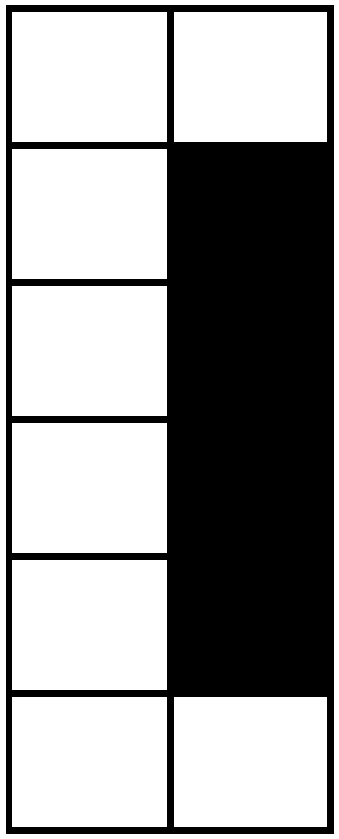

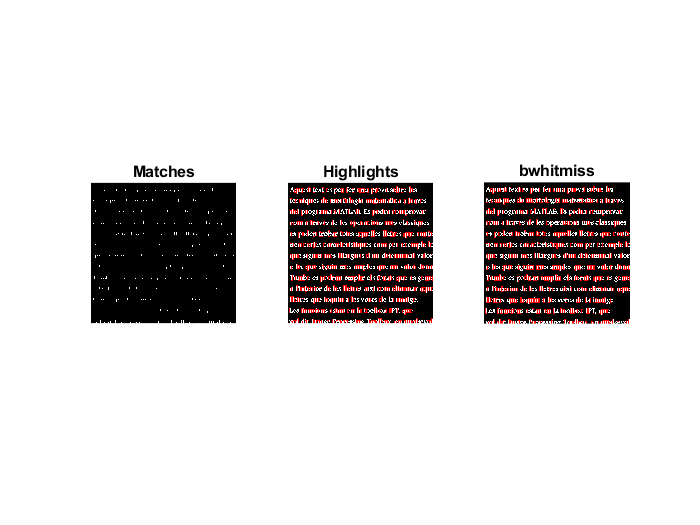

mask_W2 = [1 1;1 0;1 0;1 0;1 0;1 1];
match_W2 = imerode(f,mask_W2);

% Highlighting locations
match_W_res = imfill(imdilate(match_W2,f_mask),'holes');
match_W_res_e = imdilate(match_W2,f_mask_e);
match = match_W_res-match_W_res_e;
result_a = cat(3,f+match,f-match,f-match);

% Comparison with bwhitmiss() function
match_bwhit = bwhitmiss(f,mask_W2);
match_bwhit_res = imfill(imdilate(match_bwhit,f_mask),'holes');
match_bwhit_res_e = imdilate(match_bwhit,f_mask_e);
match = match_bwhit_res-match_bwhit_res_e;
result_hit = cat(3,f+match,f-match,f-match);

figure
subplot(1,3,1), imshow(match_W2), title('Matches')
subplot(1,3,2), imshow(result_a), title('Highlights')
subplot(1,3,3), imshow(result_hit), title('bwhitmiss')

#### b) Characters that match with the White AND the Black pixels of the pattern

- **Mask 1**

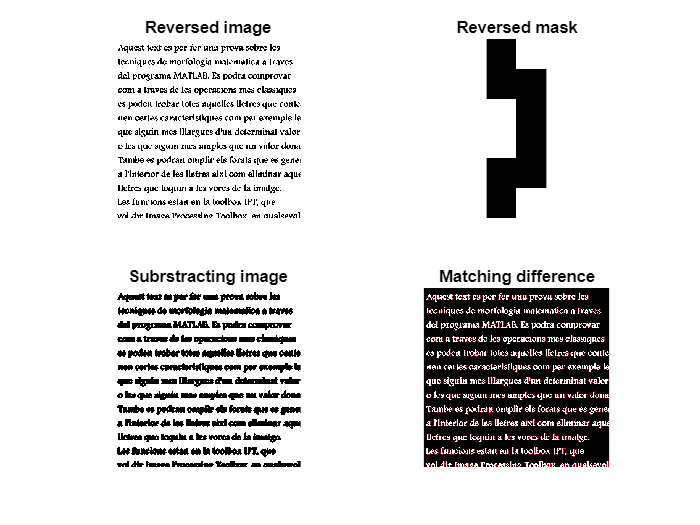

% Mask 1 for detecting black pixels
mask_B1 = ~mask_W1;                 

% Detection of black pixels
% For this we need to reverse the image so black will be white and white will be black
% Than we apply the reverse mask to this image
% To get the same image of matchin pixels in white we need to substract the
% reversed image, but sumetimes we get a match that is outside of text (see matching difference), so
% we dilate the image, then ve reverse it and than we substract
match_B1 = imerode(~f,mask_B1)-(~imdilate(f,strel('disk',1,0)));
match_B1(match_B1==-1) = 0; % Changing -1 to zero, created when substracting ~f

difference = cat(3,f+match_B1,f-match_B1,f-match_B1);

figure
subplot(2,2,1), imshow(~f), title('Reversed image')
subplot(2,2,2), imshow(mask_B1), title('Reversed mask')
subplot(2,2,3), imshow(~imdilate(f,strel('disk',1,0))), title('Subrstracting image')
subplot(2,2,4), imshow(difference), title('Matching difference')

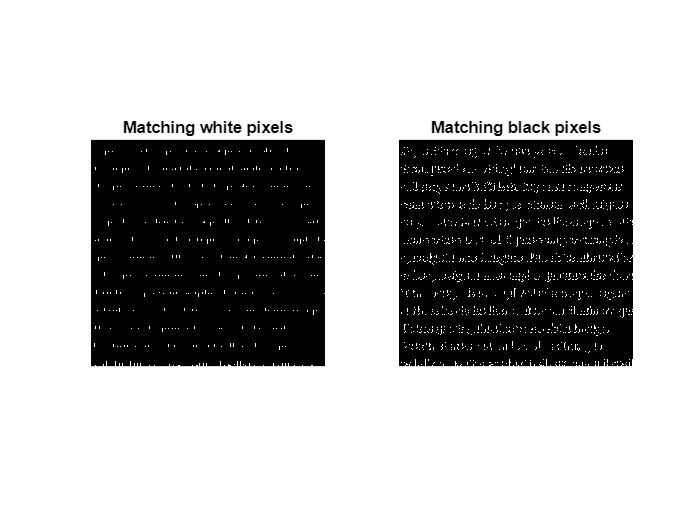


figure
subplot(1,2,1), imshow(match_W1), title('Matching white pixels')
subplot(1,2,2), imshow(match_B1), title('Matching black pixels')

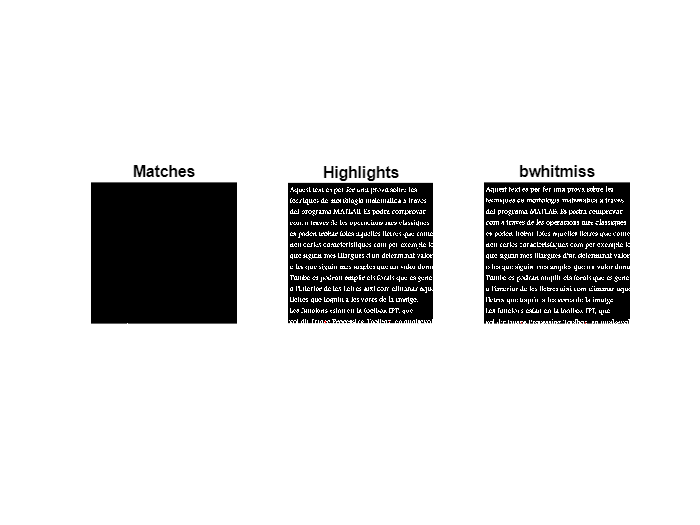

% Finding intersection of white AND black mask
match_WB1 = and(match_W1,match_B1);

% Highlighting locations
match_WB_res = imfill(imdilate(match_WB1,f_mask),'holes');
match_WB_res_e = imdilate(match_WB1,f_mask_e);
match = match_WB_res-match_WB_res_e;
result_b = cat(3,f+match,f-match,f-match);

% Comparison with bwhitmiss() function
match_bwhit = bwhitmiss(f,mask_W1,mask_B1);
match_bwhit_res = imfill(imdilate(match_bwhit,f_mask),'holes');
match_bwhit_res_e = imdilate(match_bwhit,f_mask_e);
match = match_bwhit_res-match_bwhit_res_e;
result_hit = cat(3,f+match,f-match,f-match);

figure
subplot(1,3,1), imshow(match_WB1), title('Matches')
subplot(1,3,2), imshow(result_b), title('Highlights')
subplot(1,3,3), imshow(result_hit), title('bwhitmiss')

- **Mask 2**

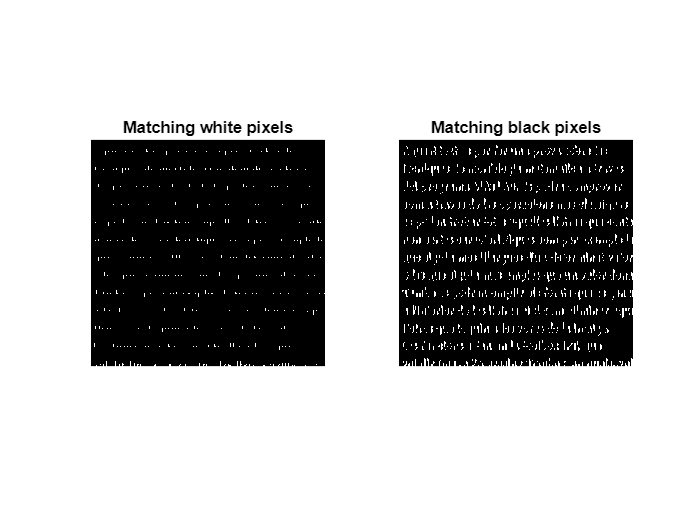

% Mask 2 for detecting black pixels 
mask_B2 = ~mask_W2;

% Detection of black pixels
match_B2 = imerode(~f,mask_B2)-(~imdilate(f,strel('disk',1,0)));
match_B2(match_B2==-1) = 0; % Changing -1 to zero created when substracting ~f

figure, 
subplot(1,2,1), imshow(match_W2), title('Matching white pixels')
subplot(1,2,2), imshow(match_B2), title('Matching black pixels')

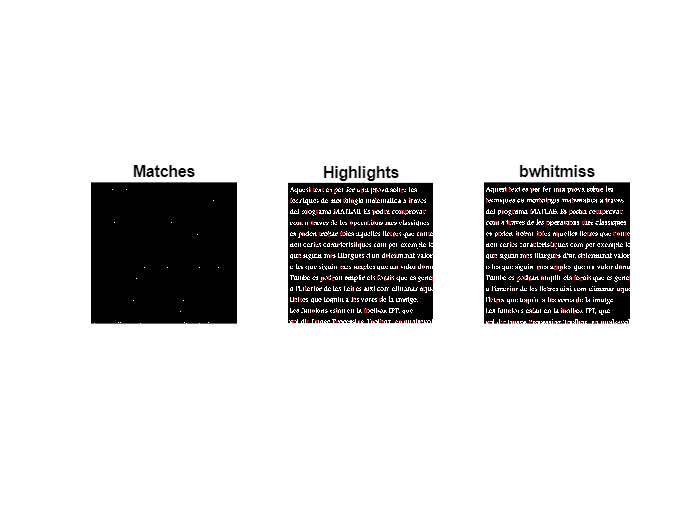

% Finding intersection of white AND black mask
match_WB2 = and(match_W2,match_B2);

% Highlighting locations
match_WB_res = imfill(imdilate(match_WB2,f_mask),'holes');
match_WB_res_e = imdilate(match_WB2,f_mask_e);
match = match_WB_res-match_WB_res_e;
result_b = cat(3,f+match,f-match,f-match);

% Comparison with bwhitmiss() function
match_bwhit = bwhitmiss(f,mask_W2,mask_B2);
match_bwhit_res = imfill(imdilate(match_bwhit,f_mask),'holes');
match_bwhit_res_e = imdilate(match_bwhit,f_mask_e);
match = match_bwhit_res-match_bwhit_res_e;
result_hit = cat(3,f+match,f-match,f-match);

figure
subplot(1,3,1), imshow(match_WB2), title('Matches')
subplot(1,3,2), imshow(result_b), title('Highlights')
subplot(1,3,3), imshow(result_hit), title('bwhitmiss')

#### 3. Find those characters that match with white AND black pixels of the next patterns, but taking into account don’t care pixels X (marked in gray with a X).

- **Mask 1**

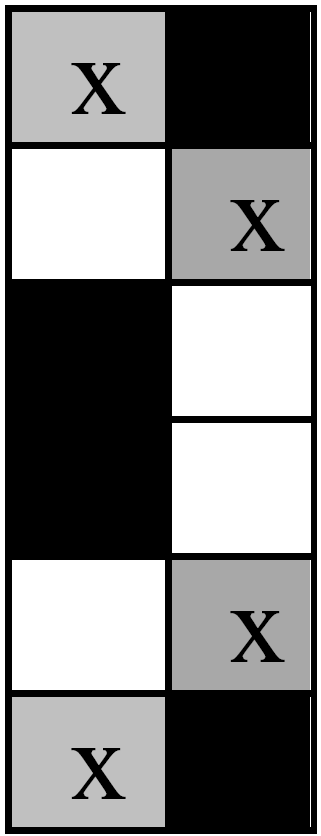

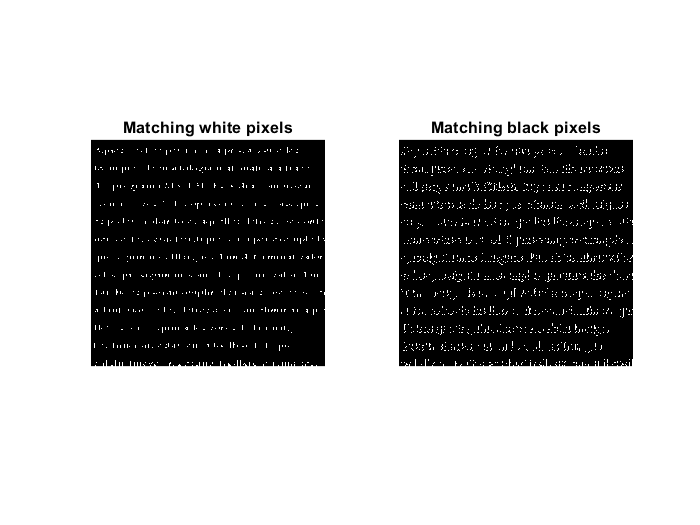

% Masks
mask_Wx1 = [0 0;1 0;0 1;0 1;1 0;0 0];
mask_Bx1 = [0 1;0 0;1 0;1 0;0 0;0 1];

% White
match_Wx1 = imerode(f,mask_Wx1);

% Black
% For this we need to reverse the image so black will be white and white will be black
% Than we apply the new mask where we only consider the black pixel, that are now white
% To get the same image of matching pixels in white we need to substract the
% reversed image, but sumetimes we get a match that is outside of text, so
% we dilate the image, then ve reverse it and than we substract
match_Bx1 = imerode(~f,mask_Bx1)-(~imdilate(f,strel('disk',1,0)));
match_Bx1(match_Bx1==-1) = 0;

figure, 
subplot(1,2,1), imshow(match_Wx1), title('Matching white pixels')
subplot(1,2,2), imshow(match_Bx1), title('Matching black pixels')

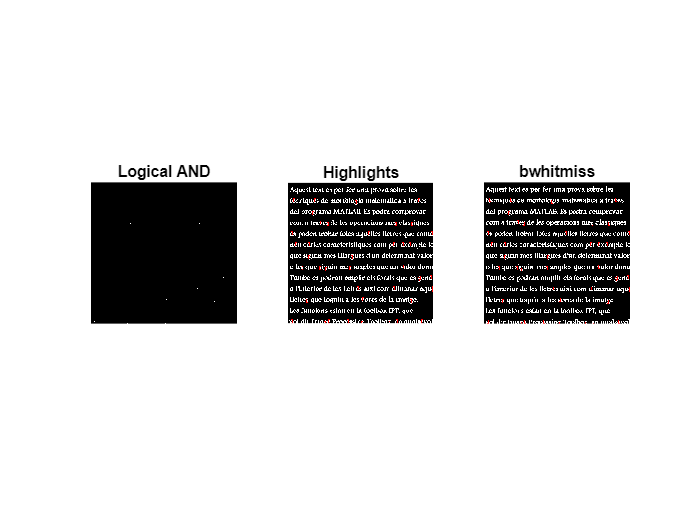

% Logical AND of both
match_WBx1 = and(match_Wx1,match_Bx1);

% Dysplaying results
match_WBx_res = imfill(imdilate(match_WBx1,f_mask),'holes');
match_WBx_res_e = imdilate(match_WBx1,f_mask_e);
match_x = match_WBx_res-match_WBx_res_e;
result_x = cat(3,f+match_x,f-match_x,f-match_x);

% Comparison with bwhitmiss() function
match_bwhit = bwhitmiss(f,mask_Wx1,mask_Bx1);
match_bwhit_res = imfill(imdilate(match_bwhit,f_mask),'holes');
match_bwhit_res_e = imdilate(match_bwhit,f_mask_e);
match = match_bwhit_res-match_bwhit_res_e;
result_hit = cat(3,f+match,f-match,f-match);

figure
subplot(1,3,1), imshow(match_WBx1), title('Logical AND')
subplot(1,3,2), imshow(result_x), title('Highlights')
subplot(1,3,3), imshow(result_hit), title('bwhitmiss')

- **Mask 2**

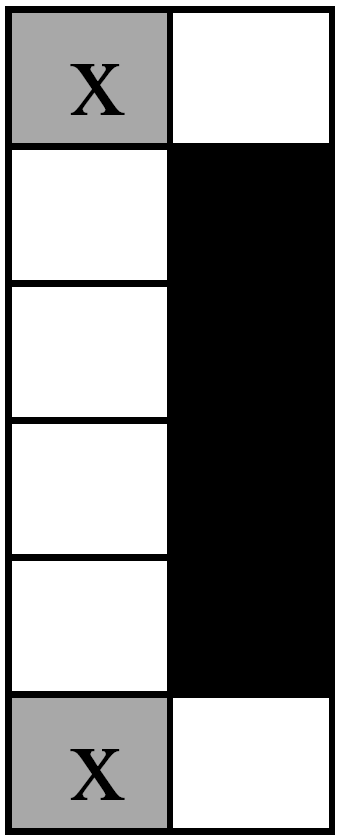

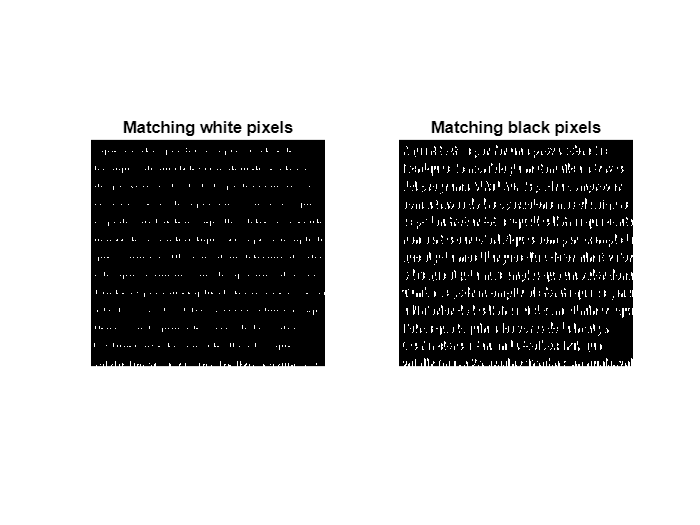

% Masks
mask_Wx2 = [0 1;1 0;1 0;1 0;1 0;0 1];
mask_Bx2 = [0 0;0 1;0 1;0 1;0 1;0 0];

% White
match_Wx2 = imerode(f,mask_Wx2);

% Black
match_Bx2 = imerode(~f,mask_Bx2)-(~imdilate(f,strel('disk',1,0)));
match_Bx2(match_Bx2==-1) = 0;

figure, 
subplot(1,2,1), imshow(match_Wx2), title('Matching white pixels')
subplot(1,2,2), imshow(match_Bx2), title('Matching black pixels')

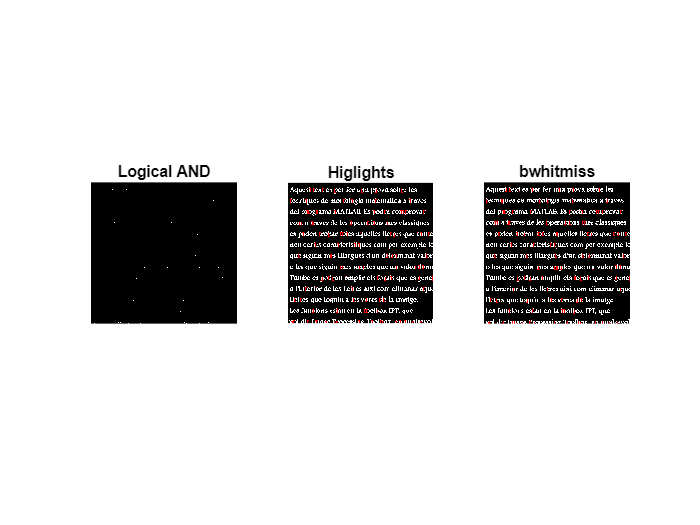

% Logical AND of both
match_WBx2 = and(match_Wx2,match_Bx2);

% Dysplaying results
match_WBx_res = imfill(imdilate(match_WBx2,f_mask),'holes');
match_WBx_res_e = imdilate(match_WBx2,f_mask_e);
match_x = match_WBx_res-match_WBx_res_e;
result_x = cat(3,f+match_x,f-match_x,f-match_x);

% Comparison with bwhitmiss() function
match_bwhit = bwhitmiss(f,mask_Wx2,mask_Bx2);
match_bwhit_res = imfill(imdilate(match_bwhit,f_mask),'holes');
match_bwhit_res_e = imdilate(match_bwhit,f_mask_e);
match = match_bwhit_res-match_bwhit_res_e;
result_hit = cat(3,f+match,f-match,f-match);

figure
subplot(1,3,1), imshow(match_WBx2), title('Logical AND')
subplot(1,3,2), imshow(result_x), title('Higlights')
subplot(1,3,3), imshow(result_hit), title('bwhitmiss')

## Exercise 2

clear; clc;
image = 'blood5.tif'      % 'bloodcells.tif' 

image = 'blood5.tif'

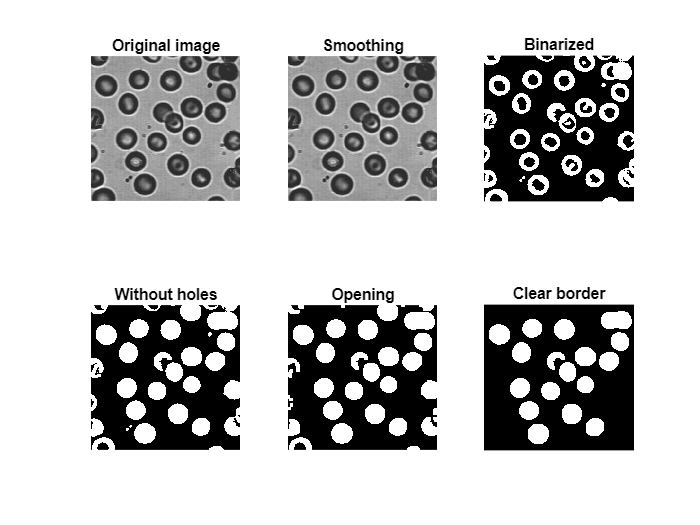

I = imread(image);

mask = fspecial('Gaussian');        %Smoothing to eliminate noise
I_f = imfilter(I,mask);

if strcmp(image,'bloodcells.tif')
    T = 0.47;                       %Best thr for bloodcells.tif
elseif strcmp(image,'blood5.tif')
    T = 0.30;                       %Best thr for blood5.tif
end
                      
%T = graythresh(I)                  %Most suitable threshold (Otsu method)

I_bin = ~imbinarize(I_f,T);         %Binarization

I2 = imfill(I_bin, 'holes');        %Filling the elements

se = ones(11);
I3 = imopen(I2,se);                 %Opening to improve results

I4 =  imclearborder(I3,8);          %Clearing the border

%Plot of the results
figure
subplot(2,3,1), imshow(I), title('Original image')
subplot(2,3,2), imshow(I_f), title('Smoothing')
subplot(2,3,3), imshow(I_bin), title('Binarized')
subplot(2,3,4), imshow(I2), title('Without holes')
subplot(2,3,5), imshow(I3), title('Opening')
subplot(2,3,6), imshow(I4), title('Clear border')

[L, n] = bwlabel (I4);
%Number of objects
n

n = 17

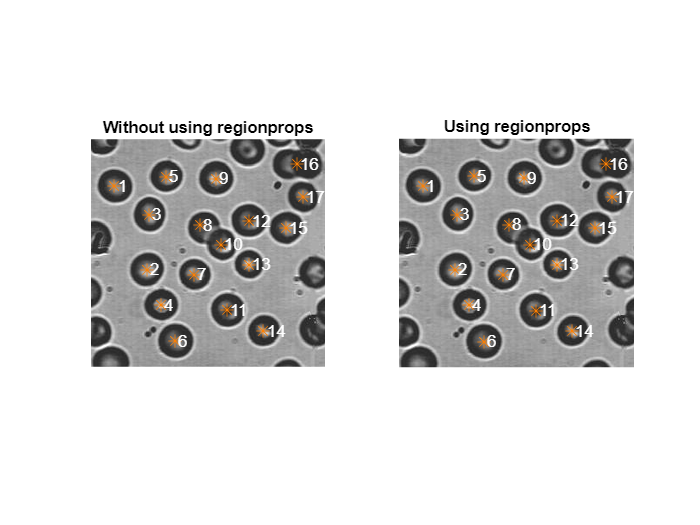

%Without using regionprops
figure
subplot(1,2,1), imshow(I), title('Without using regionprops')
hold on
for i=1:n
    object = 1*(L==i);
    [area(i), centroid(i,:)] = features(object);
    plot(centroid(i,1),centroid(i,2),'Marker','*','MarkerEdgeColor',[1 0.5 0],'MarkerFaceColor',[1 0.5 0],'MarkerSize',8);
    text(centroid(i,1)+5,centroid(i,2),num2str(i),'color','white');
    %text(centroid_2(i,1),centroid_2(i,2),num2str(i),'color','white');
end 

% Using regionprops 
subplot(1,2,2), imshow(I), title('Using regionprops')
hold on
for i=1:n
    object = 1*(L==i);
    centroid_2(i,:) = regionprops(object, 'centroid').Centroid;
    plot(centroid_2(i,1),centroid_2(i,2),'Marker','*','MarkerEdgeColor',[1 0.5 0],'MarkerFaceColor',[1 0.5 0],'MarkerSize',8);
    text(centroid_2(i,1)+5,centroid_2(i,2),num2str(i),'color','white');
end

% Rectangularity coefficient
for i=1:n
    object = 1*(L==i);
    features_2 = regionprops(object, 'Area','BoundingBox');
    A0(i) = features_2.Area;
    AR(i) = features_2.BoundingBox(3)*features_2.BoundingBox(4);
    R(i)=A0(i)/AR(i);
end
R

R =     0.8056    0.8033    0.8079    0.7920    0.7897    0.8056    0.8019    0.5352    0.8012    0.8184    0.8128    0.8192    0.8091    0.8091    0.7931    0.8550    0.8046


% Circularity coefficient
for i=1:n
    object = 1*(L==i);
    P(i) = regionprops(object, 'Perimeter').Perimeter;
    C(i) = P(i)^2/A0(i);
end
C

C =    12.2343   12.2902   12.2332   12.2613   12.2391   12.3396   12.3018   24.6446   12.1791   12.3215   12.2081   12.1984   12.1594   12.2148   12.3046   14.3283   12.2077


**Other images**

image = 'arros.tif'                 %'arros.tif'  'money.tif'  'money2.tif'

image = 'arros.tif'


I = imread(image);    

if strcmp(image,'arros.tif')
    T = 0.46;                       %Best thr for arros.tif
else
    T = graythresh(I);
end

I_bin = imbinarize(I,T);        

I2 = imfill(I_bin, 'holes');

se = ones(3);
I3 = imopen(I2,se);

I4 =  imclearborder(I3,8);

figure
subplot(2,3,1), imshow(I), title('Original image')
subplot(2,3,2), imshow(I_bin), title('Binarized')
subplot(2,3,3), imshow(I2), title('Without holes')
subplot(2,3,4), imshow(I3), title('Opening')
subplot(2,3,5), imshow(I4), title('Clear border')
[L, n] = bwlabel (I4);
n

n = 53

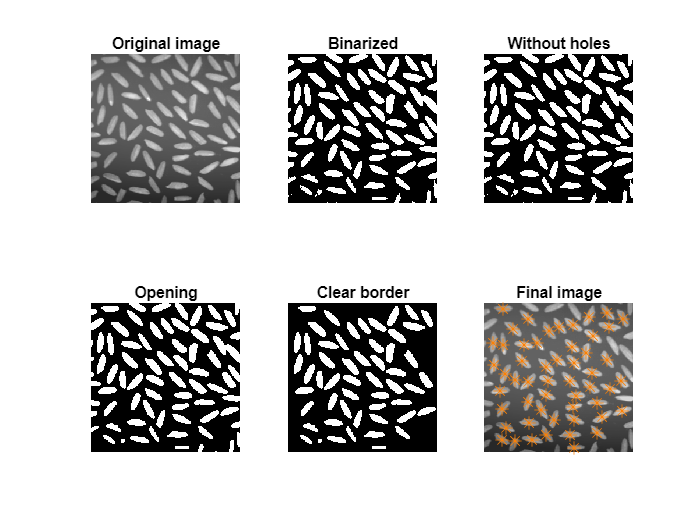

%Without using regionprops
subplot(2,3,6); imshow(I), title('Final image')
hold on
for i=1:n
    object = 1*(L==i);
    [area(i), centroid(i,:)] = features(object);
    plot(centroid(i,1),centroid(i,2),'Marker','*','MarkerEdgeColor',[1 0.5 0],'MarkerFaceColor',[1 0.5 0],'MarkerSize',8);
end 

**Use of watershed function**

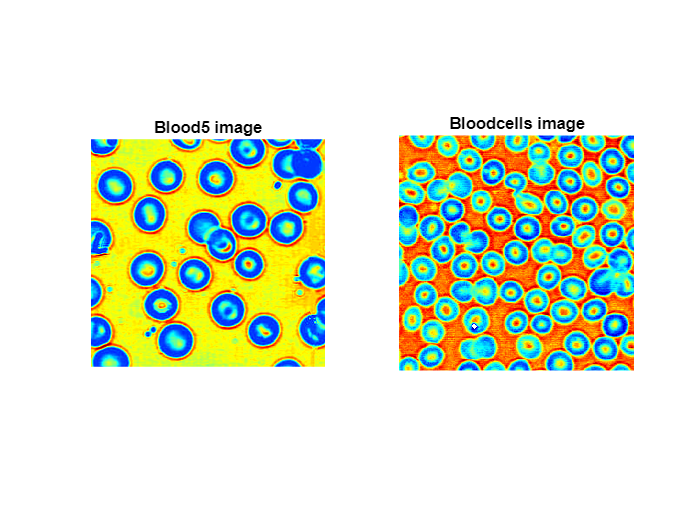

I1 = imread('blood5.tif');          %Obtaining a matrix of labels
I2 = imread('bloodcells.tif');  
rgb1 = label2rgb(I1,'jet');         %Converting the matrix into a RGB image
rgb2 = label2rgb(I2,'jet'); 

figure
subplot(1,2,1); imshow(rgb1); title('Blood5 image')
subplot(1,2,2); imshow(rgb2); title('Bloodcells image')

**Functions**

Function that computes the area and the centroid of certain shape. 

function [area, centroid] = features( F )

    [M,N] = size(F);                % dimensions of images
    [J,I] = meshgrid(1:N,1:M);
    
    m = zeros(2,2);
    for p = 1:2
        for q = 1:2
            m(p,q) = sum(sum( I.^(p-1) .* J.^(q-1) .* F ));
        end
    end
    
    % centroid
    i = m(2,1)/m(1,1);
    j = m(1,2)/m(1,1);
    
    area = m(1,1);
    centroid = [j i];
end

# Final results and conclusions

## **Exercise 1**

**First part** of the exercise where we are looking for the match of **only white pixels** was not complicated and the only thing we needet to do is the erosion of the mask, from which we obtained white pixel where the mask matches the image. 

For the **second part** where we were** also looking for exact** **location of black pixels** we needed to reverse the image so black pixels would be white and white black and also reverse the mask. Then we eroded this mask to the reversed image but we got locations on the reversed image. But we could not just reverse the solution because the locations would disapear so we substracted original image that we dilated because we could not get the matching pixel sometimes and this way we got a solution for black pixels. Then we used logical statement where we only take the same matchings for black and white pixels and found the final matches.

For the** last part** where we did **not consider parts of the mask** we applied the same process as in the second part, but the pixels that we did not cosider in the mask were always zero. This way we found the solutions for both masks. 

## **Exercise 2**

In order to obtain the results we have applied the following methods: 

- **Binarization: **The binarization is the root of most of problems, and the final solution is heavily influenced by the threshold. Based on trial and error, we have obtained the best thresholds for each one of the image. The function used is *imbinarize*. 

- **Delation of holes: **In order to work with ''stuffed things'' is necessary this step to delete all possible holes inside the geometries. It is important to take into consideration that the elements that we want to fill must be in white so, if they are not, it is necessary to invert the image first. The function used is *imfill*.

- **Opening: **To improve the results we have applied an opening (erosion + dilation). The size of the mask depends on the image. The function used is *imopen*.

- **Clear the border: **It is not possible to find the center of mass of those elements that are touching the border, so we have finally one step to delete them. The functio used is *imclearborder*. 

**Features**

- **Center of mass: **The center of mass of each element has been obtained using the *regionprops* function and our own function. Our function *features* returns the centroid and the area of each element, and as we can see the results are the same. 

- **Rectangularity coefficient: **This coefficient will get its maximum value (1.0) for rectangular objects. With the *blood5* image these coefficients are between the values 0.79 and 0.82, and with *bloodcells* image around 0.9. This difference occurs mainly because of the opening, since the cells become more square. If we decrease the size of the mask we will obtain a smaller number of cells, but the coefficients will be around 0.8 as in the previous image. 

- **Circularity coefficient: **This coefficient will get its maximum value (4*pi) for round shapes. In the blood5 image, for example, the minimum value obtained is 12.19 and the maximum 12.33 (ignoring the wrong cells), so we can conclude that logically we are very close to 4*pi = 12,56. 

**Improving the results **(*Extra bonus 1*)

In order to try to improve the results we have tried to make some changes: 

- **Binarization**: We have computed the most suitable threshold using the Otsu's method, but the obtained results have been worse than using our thresholds. The function used to apply the Otsu's method is *graythresh*.

- **Smoothing**: We have tried to to improve our solution by smoothing the image in gray  levels before binarizing. However, the results haven't changed so much and and there is only an improvement in the image *bloodcells5.tif.*

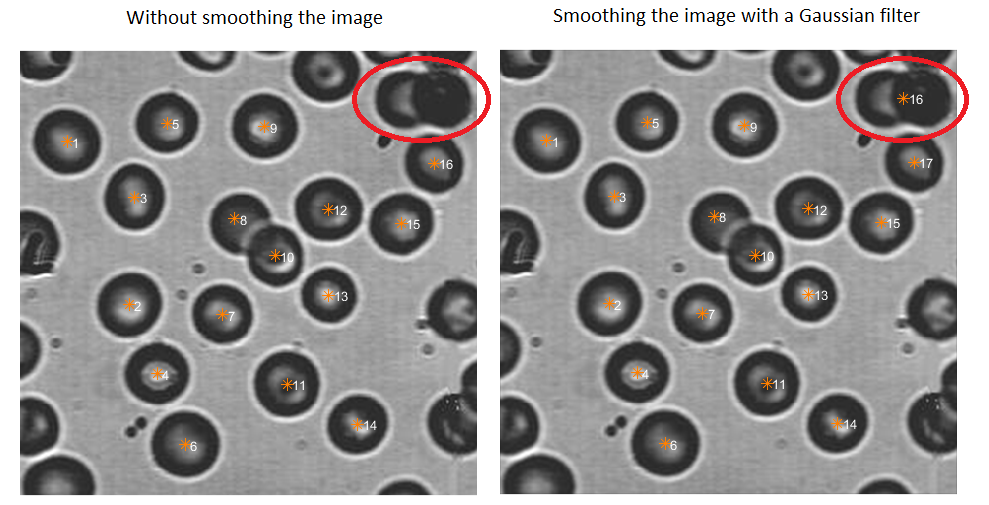

**Testing the watershed matlab function** (*Extra bonus 2*)

Watershed transformation can be used to segment contiguous regions of interest into separate objects. It returns a matrix of labels that identifies the watershed regions of the input array.

In order to see that we have converted this matrix of labels into a RGB image. 

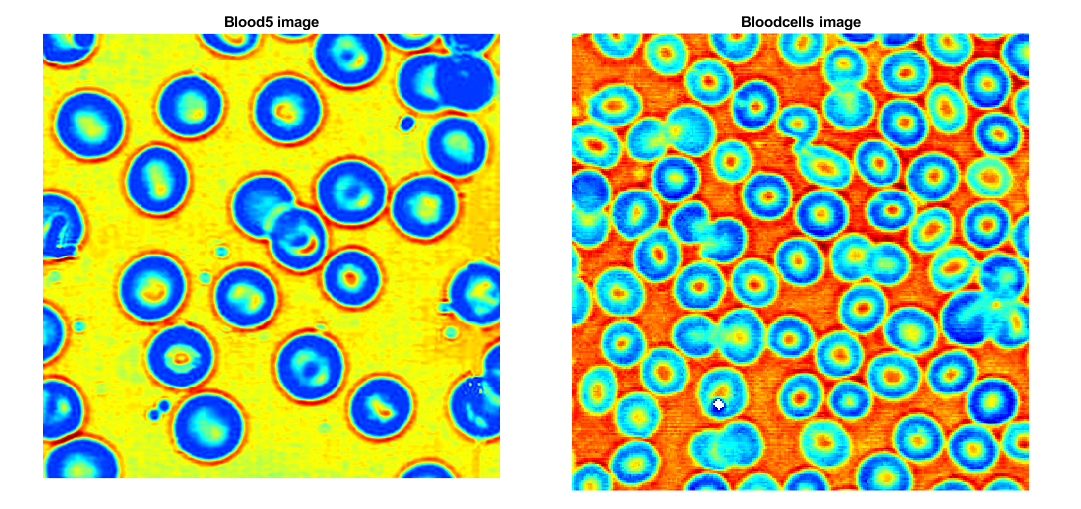

**FINAL RESULTS**

Number of elements obtained and expected of each image: